# Code to Run on 4/30

clc                     % clear command window
clear                   % clear MATLAB workspace
% profile on            % profile used to time each segment of code

## **Set up robot control system** ( code that runs once )

% % Set up Raspberry Pi
% disp('note: It takes a 10 seconds or so to download code to Raspberry PI '); 
% [robotPi, blinkLED]= RaspPiSetup()
% 
% 
% % Turn on board LED on and off to signal program has started 
% %Blink(robotPi,blinkLED,10);
% disp('Warning! Robot Rover Active! ');
% 
% % Set up servos, PiCam, and QWIIC analog input
% [roverServos] = ServoSetup(robotPi)
% [robotCam] = PiCamSetup(robotPi)
% [adcDevice1, adcDevice2] = QWIICInputSetup(robotPi)
% [neo] = GPSSetup(robotPi)


**CREATE GLOBAL VARIABLES**

load waypoints.mat
sampleTime = 0.5;                                  % Sample time [s]
t = 0:sampleTime:100;                              % Time array
r = rateControl(1/sampleTime);                     % reset control loop  rate
roverMetersPer5Secs = 10                        % 42

roverMetersPer5Secs = 10

reset(r);                                          % reset loop time to zero


**CREATE MISSION DEFINITION FILE**

% Build list of desired behaviors for Mission 1
MDFOne = table(waypoints(:,1),waypoints(:,2))      % Build Mission Definition File (MDF) table

MDFOne = 30×2 table
     Var1      Var2  
    ______    _______

    42.293    -71.264
    42.293    -71.264
    42.293    -71.264
    42.293    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264
    42.294    -71.264


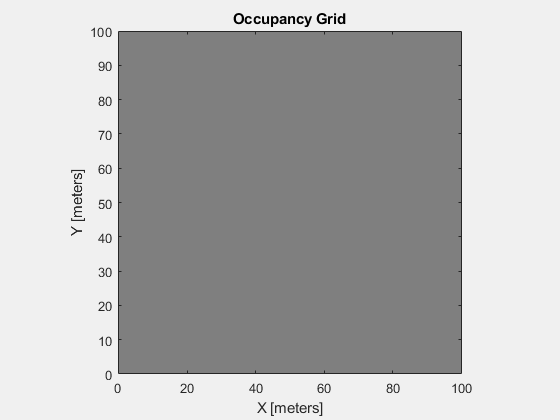

% Create an empty map of the same dimensions as the test track map                      
roverOccupancyGrid = occupancyMap(100,100);  % Make empty map the same size
% Create free floating figure (Rover occupancy grid)
figureRoverOccupancy = figure('name', 'RoverOccupancyGrid', 'NumberTitle', 'off', 'Visible', 'on');
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid);         % Show the map in figure window

distToTarget = 7.2277e-06

radius_meters = 1.0900e+07

C =   126.7456 -121.0310
  -42.1591  -21.4978


angle = -1.0513e-05

angle = -1.0513e-05

index =      0     0


index = 1

new rover location


roverLocation =  -140.1841  -71.2644


roverLocation =  -140.1841  -21.4978


New_Rover_Locations = -140.1841

New_Rover_Locations =  -140.1841  -21.4978


gridLocation = 	1.0e+07 *

   -1.8248    0.4977


New_Rover_Locations =  -140.1841  -21.4978


steeringAngle = 5

radius = -98.0251

roverLocation =  -140.1841  -21.4978


direction = 50.8017

radius_meters = 6.2106e+06

Error using test4_30_rover>circ_cent (line 445)
Circle with the specified radius does not pass through specified points

Error in test4_30_rover>GoToWayPoint (line 134)
    C = circ_cent(targetWaypoint, roverLocation, radius)

comSteer = 50;                       % set steering center
comSpeed = 50;                       % set drivespeed to zero
controlFlag = 1;                     % create a loop control
drivingSpeed = 42;

% some initial code to get out of the dock
% tic
% while toc < 3
%     % drive straight and forward
%     angle = AngleForServo(0)
%     angle = round(angle)
%     DriveRover(roverServos,angle,drivingSpeed);    
% end
% while toc < 3
%     % drive left and forward
%     angle = AngleForServo(-20)
%     angle = round(angle)
%     DriveRover(roverServos,angle,drivingSpeed);    
% end

roverLocation = [42.293252 -71.264429];
roverBearing = 100;
%starting mission
waypoint = 1;
New_Rover_Locations = [];
index = 1;
while true
    % Get Current Location
%     [roverOccupancyGrid, roverBearing, roverLocation] = GPSGetLocation(roverOccupancyGrid,neo);
%     % Pantilt and Sense
%     [roverOccupancyGrid] = MissionOneSense(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1,adcDevice2, robotCam)
    % finding target waypoint
    targetWaypoint = [MDFOne{waypoint,1} MDFOne{waypoint,2}];
    % finding behaviour to execute
    % roverBehavior = MDF{waypoint,4};
    % finding distance between rover and target waypoint
    distToTarget = norm(roverLocation-targetWaypoint);
    
    % if rover is not at the target gate, repeat WP loop
    distToTarget = deg2km(distToTarget)/1000
    while distToTarget > 0.000000005
       tic

       [New_Rover_Locations,steeringAngle,radius,roverLocation] = GoToWayPoint(roverOccupancyGrid, targetWaypoint, roverBearing, roverLocation, roverMetersPer5Secs,figureRoverOccupancy, New_Rover_Locations)
%        [steeringAngle] = roverArbiter(waypointSteeringVector)
       direction = AngleForServo(steeringAngle) 
%        while toc < 3
%            DriveRover(roverServos,direction(1),drivingSpeed);   % act on the given steering angle
%        end
       time = 3;
%        distance_travelled = velocity* time;
       
       
%        DriveRover(roverServos,direction(1),0) ;  % stop rover
       pause(1)
       % update rover location and distance to target waypoint
%        [roverOccupancyGrid, roverBearing, roverLocation] = GPSGetLocation(roverOccupancyGrid, neo);
       distToTarget = norm(roverLocation-targetWaypoint);   % update distance to target
    end
    waypoint = waypoint + 1
    if waypoint == 7
        break
    end
    
end

% shut down
% DriveRover(roverServos,50,0);
% roverServos.setServoPWM(4,0);
% roverServos.setServoPWM(5,0);

function [New_Rover_Locations, bearing,radius,roverLocation] = GoToWayPoint(roverOccupancyGrid,targetWaypoint, roverBearing, roverLocation, roverMetersPer5Secs,figureRoverOccupancy, New_Rover_Locations)
    
    %    Initialize the waypoint vector
    waypointSteeringVector = zeros(71,1);
    
    % Do math to find radius of bumblebee circle -> put in function
    xdist = abs(targetWaypoint(1) - roverLocation(2));
    ydist = abs(targetWaypoint(2) - roverLocation(1));
    omega = 360 - roverBearing;
    a = 1-cosd(omega)^2-sind(omega)^2;
    b = 2*(cosd(omega)*xdist + sind(omega)*ydist);
    c = -(xdist^2 + ydist^2);
    radius = roots([b c]);
    
    %converting radius to meters
    radius_meters = abs(deg2km(radius) * 1000)
    
    % determine left and right
    if (roverBearing > 270) && (roverBearing < 360) 
        dir = leftorright_quad2(roverLocation, roverBearing, targetWaypoint);
    else
        % in quadrants 1 and 4
        if radius > 0
            dir = "right";
        else
            dir = "left";
        end
    end
    
    % get center of circle
    C = circ_cent(targetWaypoint, roverLocation, radius)
    if C(1,1) < C(2,1)
        left_circle = C(1,:);
        right_circle = C(2,:);
    else
        left_circle = C(2,:);
        right_circle = C(1,:);
    end
 
    circumference = 2*pi*radius;
    angle = (360*km2deg(roverMetersPer5Secs*0.001)/5)/circumference

    angle = (360*km2deg(roverMetersPer5Secs*0.001)/5)/circumference
    
    index = size(New_Rover_Locations)
    index = index(1)+ 1
    if dir == "right"
        % center of bumble bee circle
        center = right_circle;
        disp('new rover location')
        roverLocation(1) = center(1)-(radius*cosd(angle))
        roverLocation(2) = center(2)+(radius*sind(angle))
        New_Rover_Locations(index, 1) = roverLocation(1)
        New_Rover_Locations(index, 2) = roverLocation(2)
    else
        center = left_circle;
        disp('new rover location')
        roverLocation(1) = center(1)+(radius*cosd(angle))
        roverLocation(2) = center(2)+(radius*sind(angle))
        New_Rover_Locations(index, 1) = roverLocation(1)
        New_Rover_Locations(index, 2) = roverLocation(2)
    end
    
    gridLocation = GPSCoordToGridIndex(roverLocation)
    updateOccupancy(roverOccupancyGrid, [gridLocation(1) gridLocation(2)], 0.2);
    updateOccupancy(roverOccupancyGrid, [gridLocation(1) gridLocation(2)], 0.2);
    figure(figureRoverOccupancy);
    show(roverOccupancyGrid); 
    bearing = 5;
end
% TODO: Methods to try to find bearing
%     bearing = ((1/radius_meters)-0.05312)/0.03153;
%     bearing = bearing - 3;
%     if bearing < 0
%         bearing = 0;
%     end

    
    % converting to bearing
%     bearing = (radius_meters - 3.1595)./(-0.0702)
%     a = .23;
%     b = 0.42;
%     c = .21;
%     bearing = asind((2*b)/(2*radius_meters+a+c))
%     if radius_meters > 30
%             bearing = 0;
%         elseif radius_meters > 20
%             bearing = 0;
%     elseif 
%         elseif radius_meters > 2.73
%             bearing = 1;
%     end
%      
    % finding the index for the turn angles to change
%      bearing = (round(bearing))
%      turnAngles = -35:1:35; % 8 vectors( y range is from -1 to 1)
%      ind = find(abs(turnAngles - bearing) <= 0.001);
% 
%     % Change the steering vector
%     waypointSteeringVector(ind) = 0.5;
% end

function[roverOccupancyGrid, roverBearing, roverLocation] = GPSGetLocation(roverOccupancyGrid, neo) % this will be provided from canvas
    basic_data = neo.getBasic();
    % roverX = basic_data.longitude
    % roverY = basic_data.lattitude
    roverLocation = [basic_data.longitude basic_data.lattitude];
    roverBearing = basic_data.heading;
    % plotting rover position on occupancy grid through conversion
%     [gridIndex] = GPSCoordToGridIndex(GPSCoordinate);
%     pvalues = 0.6; % this is the value for the rover position
%     updateOccupancy(roverOccupancyGrid,[gridIndex(1) gridIndex(2)],pvalues);
end

function [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1, adcDevice2)
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawRangeData = [rawRangeData2(1:3),rawRangeData1(1:2)];
     angles = [1 2 3 4 5; -pi/3 -pi/6 0 pi/6 pi/3]; % chagne this later     
     threshold = 40;
     for i = 1:5
        % voltage to distance     
        distance = (rawRangeData(i) - 2.805)/(-0.03316);
        if distance < threshold
            [obstaclePosX, obstaclePosY] = findGridPos(angles(i), distance, roverLocation);
            updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
        end   
     end  
end


function [obstaclePosX, obstaclePosY] = findGridPos(omega, distance, roverLocation) % Helper function for sonar / IR
    if omega < 0
            omega = 360+omega;
    elseif omega > 360
        omega = omega-360;
    end
    quo = omega/90;
    modulo = mod(omega,90);
    if floor(quo) == 0 % Quadrant I
        obstaclePosX = roverLocation(0) + (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) + (distance*sind(modulo))
    elseif floor(quo) == 1 % Quadrant IV
        obstaclePosX = roverLocation(0) + (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) - (distance*sind(modulo))
    elseif floor(quo) == 2 % Quadrant III
        obstaclePosX = roverLocation(0) - (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) - (distance*sind(modulo))
    elseif floor(quo) == 3 % Quadrant IV
        obstaclePosX = roverLocation(0) - (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) + (distance*sind(modulo))
    end
end

function [roverOccupancyGrid] = SonarRange(roverOccupancyGrid, figureRoverOccupancy, headBearing, roverLocation, adcDevice1) % fill in other variables
% Mark obstacles based on the positions on the grid

    % Sonar calibration, covert voltage data into distance measurement (cm)
    distanceLeft = (adcDevice1.readVoltage(2)-0.01063)/0.01584; 
    distanceRight = (adcDevice1.readVoltage(3)-0.01063)/0.01584;
    
    % If measured distance is within some threshold, mark it as an obstacle
    % on the occupancy grid
    threshold = 5;
    if distanceLeft < threshold
        omegaLeft = headBearing-90;
        [obstaclePosX, obstaclePosY] = findGridPos(omegaLeft, distanceLeft, roverLocation)
        updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
        
    end
    if distanceRight < threshold 
        omegaRight = headBearing-90;
        [obstaclePosX, obstaclePosY] = findGridPos(omegaRight, distanceRight, roverLocation)
        updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
    end
end



function[roverOccupancyGrid] = MissionOneSense(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1,adcDevice2, robotCam,roverJoy, roverServos)
%% TODO for sonar function, headBearing == roverBearing + (panAngle converted to global bearing)
    
    joystickControl=1
    while joystickControl == 1
        % Use joystick to move rover head, Y + enter when ready to sense
        while 1
            [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
            DrivePanTilt(panAngle, tiltAngle, roverServos)
            stop=input('Ready to sense? type Y then hit enter ','s');
            if stop == 'Y'
                break
            end
        end
        % Call all the sense functions related to Mission 1
        [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1, adcDevice2) % fill in other variable
%         [roverOccupancyGrid] = PiCamLaser(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, robotCam) % laser for obstacle avoidance
%         [roverOccupancyGrid] = PiCamObstacles(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, robotCam) % color masking for obstacles
        [roverOccupancyGrid] =  SonarRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing+panAngle, roverLocation, adcDevice1) % fill in other variables
       
        figure(figureRoverOccupancy);     % Show updated occupancy grid
            hold on;
            show(roverOccupancyGrid);
            grid on;
            grid minor;
            hold off;
        
        joystickControl=input('Keep sensing? (0-1)');
    end
end


function [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
% this function polls USB joystick and returns x position 
% for Rover steering angle and y position for Rover velocity
    stickX = axis(roverJoy, 1);     % X-axis is joystick axis 1 (-1 to 1)
    stickY = axis(roverJoy, 2);     % Y-axis is joystick axis 2 (-1 to 1)
    panAngle = 50 + (10 * stickX);  % scale X for servo with pulse centered at 50
    tiltAngle = 50 + (-10 * stickY);  % scale Y for servo with pulse centered at 50
end

function rawRangeDataN = SENSE_ADC(adcDeviceN)
     % read ADC1 Pin 0-4 voltage
    rawRangeDataN = [adcDeviceN.readVoltage(0), adcDeviceN.readVoltage(1), ...
                adcDeviceN.readVoltage(2), adcDeviceN.readVoltage(3)]; 
end

**THINK FUNCTIONS**

function [gridIndex] = GPSCoordToGridIndex(GPSCoordinate)
    bottom_left_corner = [42.293000, -71.264461];
    xgrid = (GPSCoordinate(1) - bottom_left_corner(1))/(10^(-5)); % plot it on to 100 by 100
    ygrid = (GPSCoordinate(2) - bottom_left_corner(2))/(10^(-5));
    gridIndex = [xgrid ygrid];  
end

function [steeringAngle] = roverArbiter(behavior1, behavior2, behavior3, behavior4, behavior5)
% From all the brainwaves generated from the different behaivoursav, output a final direction
    
    % If parameters are not given, default as vector of zeros
    num_behaviors = 5;
    switch nargin
        case 4
            behavior5 = zeros(1,71);
            num_behaviors = 4;
        case 3
            behavior4 = zeros(1,71);
            behavior5 = zeros(1,71);
            num_behaviors = 3;
        case 2
            behavior5 = zeros(1,71);
            behavior4 = zeros(1,71);
            behavior3 = zeros(1,71);
            num_behaviors = 2;
        case 1
            behavior5 = zeros(1,71);
            behavior4 = zeros(1,71);
            behavior3 = zeros(1,71);
            behavior2 = zeros(1,71);
            num_behaviors = 1;
    end    
    steeringVector = (behavior1 + behavior2 + behavior3 + behavior4 + behavior5)/num_behaviors;
    
    turnAngles =  -35:1:35; % 8 vectors( y range is from -1 to 1)
    
%     figure(figureArbiter)                 % go to brain waves figure
%     %clf                               % clear figure of old waves
%     plot(turnAngles, behavior1, "b-+");        % plot behaviour 1 waveform
%      ax=gca;
%      ax.XDir = 'reverse';
%     axis([-8 8 -8 8]);
%     grid on;
%     grid minor;
%     hold on
%     plot(turnAngles, behavior2, "g-+");
%     plot(turnAngles, behavior3, "c-o");
%     plot(turnAngles, behavior4, "y-o");
%     plot(turnAngles, behavior5, "b-o");
%     
%     plot(turnAngles, steeringVector, "r-+");       % plot sum of steer angle waveform
%     legend('behavior1','behavior2','behavior3','behavior4','behavior5') % label plot
%     hold off
    
    [x,ind] = max(steeringVector);
    steeringAngle = turnAngles(ind)    
end

function pwm = AngleForServo(angle)
pwm = ((angle + 85.21)/1.755) - .6;
end

function [turn] = leftorright_quad2(roverLocation, roverBearing, waypoint)  
    A = roverLocation;    
    point_x= roverLocation(1) + 2*cosd(roverBearing) % point 2
    point_y = roverLocation(2) + 2*sind(roverBearing)% point2
    B = [point_x point_y];
%     line_eq = k*x + n
%     P = (a,b)
    k = (A(2) - B(2))/(A(1) - B(1));
    n = A(2) - k*A(1);
    
    a = waypoint(1);
    b = waypoint(2);
    
   
    if k*a + n > b
        turn = 'right';
    elseif k*a + n < b
        turn = 'left';
    else
        turn = 'on the line';
    end
end

function [C]=circ_cent(P1,P2,R)
%Inputs:
    %P1-First point e.g. [3 4] => (x1,y1)
    %P2-Second point  
    %R-Radius
%Output:
    %C-Center of the circle. Its a 2x2 matrix. First row represents first 
    %possible center (x1,y1) and second row is the second possible center
    
    if(~(isreal(P1) && isreal(P2) && isreal(R)))
        error('Invalid/Complex inputs');
    end
    
        
    a=P1(1)^2-P2(1)^2;
    b=P1(2)^2-P2(2)^2;
    c=-2*(P1(1)-P2(1));
    d=-2*(P1(2)-P2(2));
    e=a+b;
    Coeff1=1+(d/c)^2;
    Coeff2=((2*d*e/c^2)+(P2(1)*2*d/c)-2*P2(2));
    Coeff3=((e/c)^2+(2*P2(1)*e/c)+P2(1)^2+P2(2)^2-R^2);
    All_coeff=[Coeff1 Coeff2 Coeff3];
    Eq_root=roots(All_coeff);
    C=zeros(length(Eq_root),2);
    for i=1:length(Eq_root)
        x=-(e+d*Eq_root(i))/c;
        C(i,1)=x;
        C(i,2)=Eq_root(i);
    end
    if(~isreal(C))
        error('Circle with the specified radius does not pass through specified points');
    end
end

**ACT FUNCTIONS**

function [] = DrivePanTilt(panAngle, tiltAngle, roverServos)
     roverServos.setServoPWM(4,panAngle);    % commands panning servo
     roverServos.setServoPWM(5,tiltAngle);   % commands tilting servo
end

function [] = DriveRover(roverServos,direction,speed)
     roverServos.setServoPWM(1,direction);    % commands steering servo
     roverServos.setServoPWM(2,speed);    % commands drive speed controller
end

**SETUP PI**

function [robotPi, blinkLED] = RaspPiSetup()
% RaspPiSetup creates and configures a Raspberry Pi to be a simple robot 
% controller. It requires no inputs and returns a rasPi object

% Create a *raspi* object.
%    robotPi = raspi('192.168.16.65', 'pi', 'raspberry');   % lab pi
   robotPi = raspi('192.168.34.15', 'pi', 'raspberry');   % melody pi
 
% There is a user LED on Raspberry Pi hardware that you can turn on and
% off. Execute the following command at the MATLAB prompt to turn the LED
% off and then turn it on again.
   blinkLED = robotPi.AvailableLEDs{1};
end

**SETUP SERVOS**

function [roverServos] = ServoSetup(robotPi)
% Check everything is plugged in on i2c Qwiic bus (should see devices at  servo 0x40, GPS 0x42, ADC 0x48 0x49, Pi 0x70 
scanI2CBus(robotPi)

% Configure Servo pHAT driver board (address 0x40), set servos to null position.
roverServos = I2C_Servo_pHAT(robotPi);
pSteer = 1;                                   % set Steer servo to pin 1
pSpeed = 3;                                   % set Speed servo to pin 3
comSteer = 50;                                % set intial steer command to 0 angle
comSpeed = 50;                                % set intial speed command to 0 speed
roverServos.setServoPWM(pSteer,comSteer);     % Set sterring servo  center position
roverServos.setServoPWM(pSpeed,comSpeed);     % Set Rover speed  zero

% Define joystick ID (if only using 1 joystick, this will likely be '1')
% ID = 1;

% Create joystick variable
% roverJoy=vrjoystick(ID);

% Visualize the test servo commands in robot coordinate system.
% create a new free-standing figure to display the servo data, rover
% at center
localServoPlot=figure('Name','RoverServoSettings (trigger to STOP)','NumberTitle','off','Visible','on');
PlotServoSettings(localServoPlot,comSteer,comSpeed)
end

function [] = PlotServoSettings(localServoPlot,comSteer, comSpeed)
    % Plots Rover's steerig angle and speed on a stand alone figure
    figure(localServoPlot)
    plot(comSteer,comSpeed, 'r*');
    axis([30 70 30 70]);
    grid on;
    grid minor;
    xlabel('Actual Steer Servo Setpoint')
    ylabel ('Actual Speed Servo Setpoint')
    hold on;
    plot(50,50, 'g^');             % plot robot position 
    hold off;  
end


**SETUP PICAM**

function [robotCam] = PiCamSetup(robotPi)
% To create a connection to the V2 Pi Camera
robotCam = cameraboard(robotPi,'Resolution','320x240');

% Fix auto exposure problem , set eposure to work in lab lighting
% set whitebalance to manual too. Auto exposure and white balance drive
% computer vison algorithms crazy by constantly changing
SetUpPiCamera(robotCam);
end

function []= SetUpPiCamera(robotCam)
    % creates and configures an Pi V2 Camera to be a simple robot 
    % vision system. It requires a standard Pi V2 cmaera attached to 
    % your Raspberry piand takes the picam object name as sole input
    % You need to set your cameras unique parameters to optimize picture
    % D. Barrett 2021 Rev A
    % Available resolutions: '160x120', '320x240', '640x480', '800x600', '1024x768', '1280x720', '1920x1080'
    % Available exposure modes: 'auto', 'night', 'nightpreview', 'backlight', 'spotlight', 'sports', 'snow', 
    % 'beach', 'verylong', 'fixedfps', 'antishake', 'fireworks'
    % Available AWB modes: 'off', 'auto', 'sun', 'cloud', 'shade', 'tungsten', 'fluorescent', 
    % 'incandescent', 'flash', 'horizon'
    % Available metering modes: 'average', 'spot', 'backlit', 'matrix'
    % Available image effects: 'none', 'negative', 'solarise', 'sketch', 'denoise', 
    % 'emboss', 'oilpaint', 'hatch', 'gpen', 'pastel', 'watercolour', 'film', 'blur', 'saturation', 'colourswap', 'washedout', 'posterise', 'colourpoint', 'colourbalance', 'cartoon'

    % Fix  exposure set it to respond quickly, set auto whitebalance to off
    robotCam.ExposureMode = 'sports';
    robotCam.AWBMode = 'fluorescent';
end


**SETUP QWIIC ANALOG INPUT**

function [adcDevice1, adcDevice2] = QWIICInputSetup(robotPi)
% create two SparkFun Qwiic Analog Input adc device that are present on i2c
% bus 1 at address 0x48 and at adress 0x49

adcDevice1 = ads1015(robotPi,'i2c-1','0x48'); % 2 sonar sensor and 2 IR
adcDevice2 = ads1015(robotPi,'i2c-1','0x49'); % 3 IR sensors

rawRangeData1 = SENSE_ADC(adcDevice1)
rawRangeData2 = SENSE_ADC(adcDevice2)
rawRangeData = [rawRangeData1,rawRangeData2];  % concatinate ADC raw vectors together
% Visualize the test sensor scan data in robot coordinate system.
% create a new free-standing figure to display the local sensor data, rover
% at center
localSensorPlot=figure('Name','LocalSensorMap','NumberTitle','off','Visible','on');
PlotSensorData(localSensorPlot, rawRangeData);
end

function [] = PlotSensorData(localSensorPlot, rawRangeData)
    % Plots Rover Sensor Data on a standalone figure
    figure(localSensorPlot)
    plot(rawRangeData)
    axis([1 8 0 3.5]);
    grid on;
    grid minor; 
    xlabel('Sensor Station')
    ylabel ('Raw Sensor Voltage')
    hold on;
    plot(4.5,0, 'r*');             % plot robot position 
    hold off;  
end


**SETUP GPS**

function [neo] = GPSSetup(robotPi)
neo = NEO_M8U(robotPi);            % Create a GPS Class Instance
pause(2);                          % Let GPS get up to speed
% returns a struct with fields: longitude, lattitude, roll, pitch, and heading.
end

**SETUP JOYSTICK**

function [roverJoy] = JoystickSetup(joystickID)
 % Create joystick variable
   roverJoy=vrjoystick(ID);
end